# Burned Expansion Phase

This is essentially the same as Compression Phase analysis, but this is for burned expansion phase.

Polytropic process


$$p_e \left(\theta \text{ }\right)=p_3 {\left(\frac{V_{\text{ivc}} }{V\left(\theta \text{ }\right)}\right)}^{k_e }$$



$$T_e \left(\theta \text{ }\right)=T_3 {\left(\frac{V_{\text{ivc}} }{V\left(\theta \text{ }\right)}\right)}^{k_e -1}$$


params_cylinder
x = linspace(-pi, pi, 100);
Vx = cylinder_volume_mm3_matlab(x, params.cylinder.V_c_mm3, params.cylinder.a_mm, params.cylinder.l_mm, params.cylinder.B_mm);

Otty-cycle parameters

p3_kPa = params.cylinder.p3_kPa;
T3_K = params.cylinder.T3_K;
k_e = 1.3;  % a literature value
V3_mm3 = params.cylinder.V_tdc_mm3;

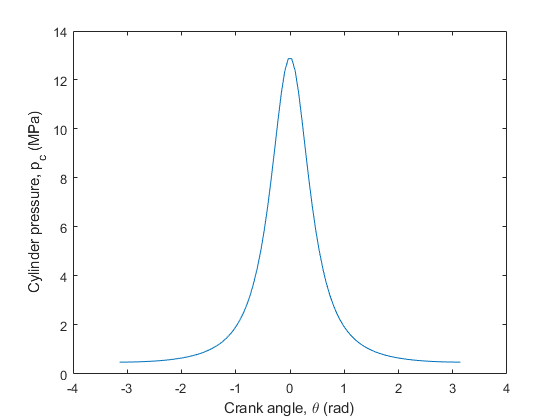

p_e_x = p3_kPa.*( V3_mm3 ./ Vx ).^k_e;  % polytropic process
figure
plot(x, p_e_x/1e3)  % plot in MPa, instead of kPa
xlabel('Crank angle, \theta (rad)')
ylabel('Cylinder pressure, p_c (MPa)')

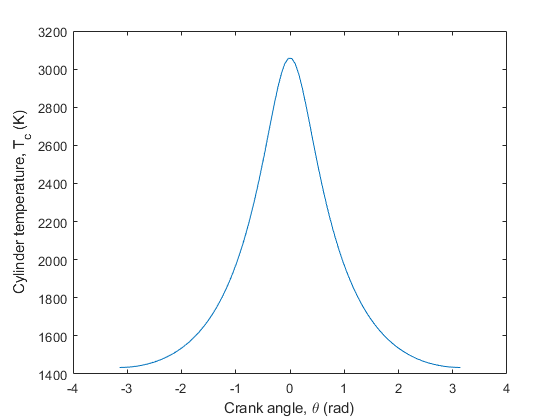

T_e_x = T3_K.*( V3_mm3 ./ Vx ).^(k_e - 1);  % polytropic process
figure
plot(x, T_e_x)
xlabel('Crank angle, \theta (rad)')
ylabel('Cylinder temperature, T_c (K)')